clc; clear; close all;

## KITTI数据集可视化

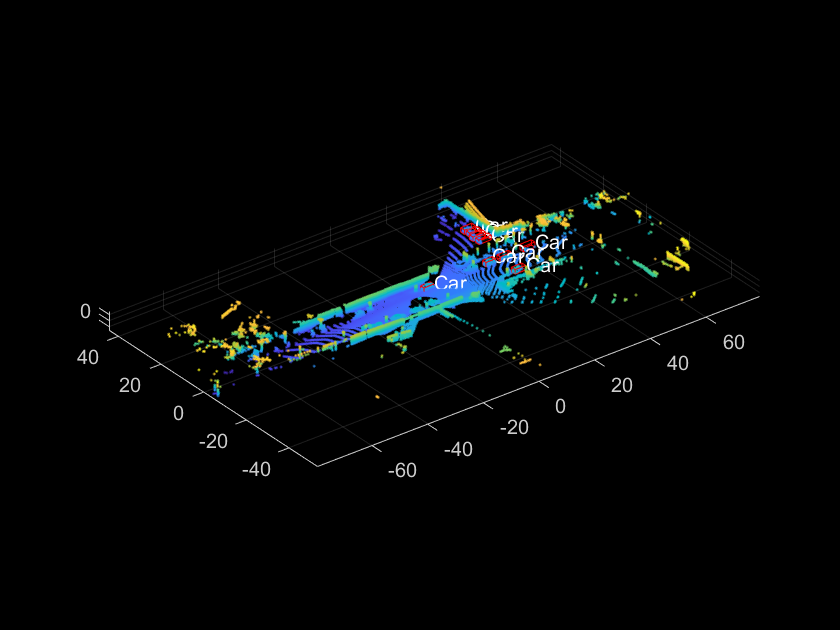

file = '003224';   % 文件编号

fid=fopen(['./training/velodyne/',file,'.bin'],'rb');
%以float32的格式将数据存放在列向量中
[a,count]=fread(fid,'float32');
fclose(fid);
x = a(1:4:end);
y = a(2:4:end);
z = a(3:4:end);
data = pointCloud([x y z]);
figure(1);
pcshow(data);hold on;

label = importdata(['./training/label/',file,'.txt']);
obsName = label.textdata;
data_label = label.data;
obsNum = size(data_label,1);

data_calib = importdata(['./training/calib/',file,'.txt']);
Tr_velo_to_cam = reshape(data_calib.data(end-1,:),[4,3])';
Tr_velo_to_cam = [Tr_velo_to_cam;0 0 0 1];

for i = 1:obsNum
    if obsName{i} == "DontCare"
        continue;
    end
    la = data_label(i,:);
    obsPos = la(11:13)';
    [h,w,l] = deal(la(8),la(9),la(10));
    r_y = la(end);
    
    % obsPos_velo = Tr_cam_to_velo*[obsPos;1];
    % obsPos_velo = obsPos_velo(1:3)
    % t1~t8为障碍物坐标系下的坐标（不考虑障碍物旋转，默认长边与x-axis平行）
    t1 = [l/2,0,w/2];
    t2 = [l/2,0,-w/2];
    t3 = [l/2,-h,w/2];
    t4 = [l/2,-h,-w/2];
    t5 = [-l/2,0,w/2];
    t6 = [-l/2,0,-w/2];
    t7 = [-l/2,-h,w/2];
    t8 = [-l/2,-h,-w/2];
    % 考虑障碍物旋转角度r_y，对x,z方向进行更新
    T = [t1;t2;t3;t4;t5;t6;t7;t8];
    R = [cos(r_y),-sin(r_y);sin(r_y),cos(r_y)];
    T(:,[1,3]) = (R*T(:,[1,3])')';
    % 考虑障碍物坐标系与相机坐标系坐标位移
    T(:,1) = T(:,1) + obsPos(1);
    T(:,2) = T(:,2) + obsPos(2);
    T(:,3) = T(:,3) + obsPos(3);
    % 将相机坐标系转化到激光雷达坐标系
    velo_pos = Tr_velo_to_cam\[T';1,1,1,1,1,1,1,1];
    velo_pos = velo_pos(1:3,:);
    % 绘制12根线构成3D-Box
    temp = [velo_pos(:,3),velo_pos(:,4),velo_pos(:,7),velo_pos(:,8)];
    [~,j] = max([velo_pos(1,3),velo_pos(1,4),velo_pos(1,7),velo_pos(1,8)]);
    textPoint = temp(:,j);
    text(textPoint(1),textPoint(2),textPoint(3)+0.5,obsName{i},'Color','white');
    plot3(velo_pos(1,[1,2,6,5,1]),velo_pos(2,[1,2,6,5,1]),velo_pos(3,[1,2,6,5,1]),'Color','r');
    plot3(velo_pos(1,[3,4,8,7,3]),velo_pos(2,[3,4,8,7,3]),velo_pos(3,[3,4,8,7,3]),'Color','r');
    plot3(velo_pos(1,[1,3]),velo_pos(2,[1,3]),velo_pos(3,[1,3]),'Color','r');
    plot3(velo_pos(1,[2,4]),velo_pos(2,[2,4]),velo_pos(3,[2,4]),'Color','r');
    plot3(velo_pos(1,[6,8]),velo_pos(2,[6,8]),velo_pos(3,[2,4]),'Color','r');
    plot3(velo_pos(1,[5,7]),velo_pos(2,[5,7]),velo_pos(3,[5,7]),'Color','r');
end